syms t S x z
T = input('Please input how much time until maturity: ');
K = input('Please input the strike price: ');
r = input('Please input the risk-free rate of return percentage: ');
sigma = input('Please input the volatility percentage: ')

sigma = 30

r = r/100;
sigma = sigma/100

sigma = 0.3000

d1 = 1/(sigma * sqrt(t))*(log(S/K) + (r + sigma * sigma * 0.5)*(t))

$$d1 = \frac{10\,\left(\frac{19\,t}{200}+\log\left(\frac{S}{25}\right)\right)}{3\,\sqrt{t}}$$

d2 = d1 - sigma*sqrt(t)

$$d2 = \frac{10\,\left(\frac{19\,t}{200}+\log\left(\frac{S}{25}\right)\right)}{3\,\sqrt{t}}-\frac{3\,\sqrt{t}}{10}$$

PV = K * exp(-r*(t))

$$PV = 25\,{\mathrm{e}}^{-\frac{t}{20}}$$

f = 1/(sqrt(2*pi))*int(exp((-z^2)/2),z, [-inf x])

$$f = \frac{7186705221432913\,\sqrt{2}\,\sqrt{\pi }\,\left(\mathrm{erf}\left(\frac{\sqrt{2}\,x}{2}\right)+1\right)}{36028797018963968}$$

N1 = subs(f,x,d1)

$$N1 = \frac{7186705221432913\,\sqrt{2}\,\sqrt{\pi }\,\left(\mathrm{erf}\left(\frac{5\,\sqrt{2}\,\left(\frac{19\,t}{200}+\log\left(\frac{S}{25}\right)\right)}{3\,\sqrt{t}}\right)+1\right)}{36028797018963968}$$

N2 = subs(f,x,d2)

$$N2 = \frac{7186705221432913\,\sqrt{2}\,\sqrt{\pi }\,\left(\mathrm{erf}\left(\frac{\sqrt{2}\,\left(\frac{10\,\left(\frac{19\,t}{200}+\log\left(\frac{S}{25}\right)\right)}{3\,\sqrt{t}}-\frac{3\,\sqrt{t}}{10}\right)}{2}\right)+1\right)}{36028797018963968}$$

C = N1 * S - N2 * PV

$$C = \begin{array}{l} \frac{7186705221432913\,\sqrt{2}\,S\,\sqrt{\pi }\,\left(\mathrm{erf}\left(\frac{5\,\sqrt{2}\,\sigma_{1}}{3\,\sqrt{t}}\right)+1\right)}{36028797018963968}-\frac{179667630535822825\,\sqrt{2}\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{t}{20}}\,\left(\mathrm{erf}\left(\frac{\sqrt{2}\,\left(\frac{10\,\sigma_{1}}{3\,\sqrt{t}}-\frac{3\,\sqrt{t}}{10}\right)}{2}\right)+1\right)}{36028797018963968}\\ \mathrm{where}\\ \sigma_{1}=\frac{19\,t}{200}+\log\left(\frac{S}{25}\right) \end{array}$$

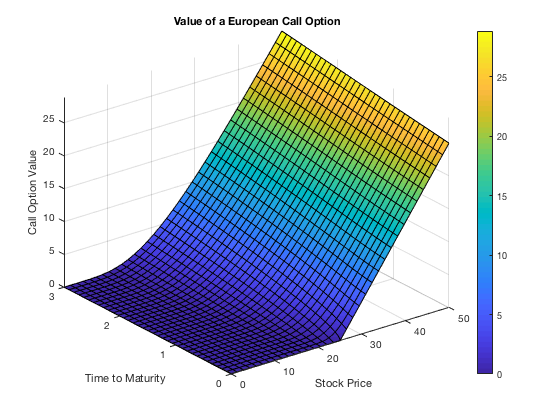

fsurf(C, [0 50 0 T])
shading interp;
colorbar;
title('Value of a European Call Option')
xlabel('Stock Price')
ylabel('Time to Maturity')
zlabel('Call Option Value')

more = input('Would you like to find the value of a call option given a specific stock price and time? ')

more = 2

if more == 1
    newS = input('What is the specific Stock price? ')
    newT = input('How long until maturity? ')
    C = subs(C,S,newS)
    ans = double(subs(C,t,newT))
    disp(ans)
end
